%% Problem 1 (strict to Exercise 2.32 and 2.33)
clear; clc; close all;

% Use current folder first (best for Live Editor). Fallback to script location.
thisDir = pwd;
mainFile = fullfile(thisDir, 'mhint_01_01.wav');
if ~isfile(mainFile)
    altDir = fileparts(which('problem1_solution.m'));
    if ~isempty(altDir)
        mainFile = fullfile(altDir, 'mhint_01_01.wav');
        thisDir = altDir;
    end
end
if ~isfile(mainFile)
    error(['Cannot find mhint_01_01.wav. Please set MATLAB Current Folder to:\n', ...
           '/Users/hwy/Desktop/个人/26春/语音信号处理/lab1']);
end

% Required parameters from the assignment.
fstart = 2000;
N = 22000;

% M must represent 100 ms of speech and depends on Fs.
info = audioinfo(mainFile);
Fs = info.SampleRate;
M = round(0.1 * Fs);

fprintf('Problem 1 strict parameters:\n');

Problem 1 strict parameters:


fprintf('Fs = %d Hz, fstart = %d, M = %d (100 ms), N = %d\n', Fs, fstart, M, N);

Fs = 16000 Hz, fstart = 2000, M = 1600 (100 ms), N = 22000


Loaded: /Users/hwy/Desktop/个人/26春/语音信号处理/lab1/mhint_01_01.wav
Fs = 16000 Hz, total samples = 59670, duration = 3.729 s
Using fstart = 2000, M = 1600, N(requested) = 22000, N(actual) = 22000
Playing original speech...


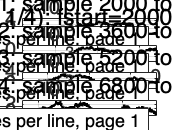

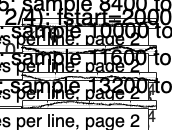

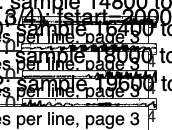

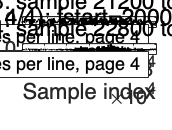

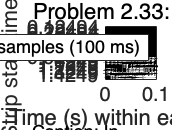


% This call generates both:
%   - Exercise 2.32 pages (manual 4 lines/page)
%   - Exercise 2.33 strips_modified single-page plot
[x, fs, xSeg] = load_play_plot(mainFile, fstart, M, N, true, 'k'); %#ok<ASGLU>


fprintf('\nProblem 1 finished: 2.32 and 2.33 are both generated.\n');


Problem 1 finished: 2.32 and 2.33 are both generated.
